% %10
% [H, g, A1, A2, b1, b2] = generate_random_qp(10,3,2);
% y = ADMM_QP(A1,A2,-b1,-b2,g,H)
% QP_10 = y'*H*y/2+g'*y;
% 
% x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
% Scale_QP_10 = x' * H * x / 2 + g' * x;
% 
% 
% [A, l, u] = standard_constraints(A2,b2,A1,b1);
% 
% m = osqp;
% m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
% results = m.solve();
% x = results.x
% Optimal_10 = x'*H*x/2+g'*x;
% 
% 
% 
% %20
% [H, g, A1, A2, b1, b2] = generate_random_qp(20,4,4);
% y = ADMM_QP(A1,A2,-b1,-b2,g,H)
% QP_20 = y'*H*y/2+g'*y;
% 
% x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
% Scale_QP_20 = x' * H * x / 2 + g' * x;
% 
% 
% [A, l, u] = standard_constraints(A2,b2,A1,b1);
% 
% m = osqp;
% m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
% results = m.solve();
% x = results.x
% Optimal_20 = x'*H*x/2+g'*x;



% %50
% [H, g, A1, A2, b1, b2] = generate_random_qp(50,10,10);
% y = ADMM_QP(A1,A2,-b1,-b2,g,H)
% QP_50 = y'*H*y/2+g'*y;
% 
% x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
% Scale_QP_50 = x' * H * x / 2 + g' * x;
% 
% 
% [A, l, u] = standard_constraints(A2,b2,A1,b1);
% 
% m = osqp;
% m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
% results = m.solve();
% x = results.x
% Optimal_50 = x'*H*x/2+g'*x;


%100
[H, g, A1, A2, b1, b2] = generate_random_qp(100,20,20);
y = ADMM_QP(A1,A2,-b1,-b2,g,H)

y =     0.1095
   -0.1067
   -0.1076
    0.0324
   -0.0613
   -0.0353
    0.0233
    0.2711
   -0.0696
    0.1559


QP_100 = y'*H*y/2+g'*y;

x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
Scale_QP_100 = x' * H * x / 2 + g' * x;


[A, l, u] = standard_constraints(A2,b2,A1,b1);

m = osqp;
m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 40
          nnz(P) + nnz(A) = 9050
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



results = m.solve();

iter  objective    pri res    dua res    rho        time
   1  -6.4843e-01   2.35e+00   1.57e+04   1.00e-01   1.78e-03s
  50   6.3117e+00   3.29e-08   2.02e-07   1.86e-02   3.14e-03s

status:               solved
number of iterations: 50
optimal objective:    6.3117
run time:             3.38e-03s
optimal rho estimate: 1.42e-02



z = results.x

z =     0.1095
   -0.1067
   -0.1076
    0.0324
   -0.0613
   -0.0353
    0.0233
    0.2711
   -0.0696
    0.1559


Optimal_100 = z'*H*z/2+g'*z;


%150
[H, g, A1, A2, b1, b2] = generate_random_qp(150,30,30);
y = ADMM_QP(A1,A2,-b1,-b2,g,H)

y =    -0.0787
    0.0082
    0.0736
   -0.0403
   -0.0550
    0.0059
    0.0827
   -0.0650
   -0.0900
   -0.0875


QP_150 = y'*H*y/2+g'*y;

x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
Scale_QP_150 = x' * H * x / 2 + g' * x;


[A, l, u] = standard_constraints(A2,b2,A1,b1);

m = osqp;
m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 150, constraints m = 60
          nnz(P) + nnz(A) = 20325
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



results = m.solve();

iter  objective    pri res    dua res    rho        time
   1  -8.5163e-01   1.96e+00   2.61e+04   1.00e-01   6.56e-03s
  75   7.6832e+00   1.87e-09   7.63e-10   1.53e-02   1.28e-02s

status:               solved
number of iterations: 75
optimal objective:    7.6832
run time:             1.32e-02s
optimal rho estimate: 3.79e-02



z = results.x

z =    -0.0787
    0.0082
    0.0736
   -0.0403
   -0.0550
    0.0059
    0.0827
   -0.0650
   -0.0900
   -0.0875


Optimal_150 = z'*H*z/2+g'*z;

%200
[H, g, A1, A2, b1, b2] = generate_random_qp(200,40,40);
y = ADMM_QP(A1,A2,-b1,-b2,g,H)

y =     0.0191
   -0.0603
    0.0563
   -0.1397
    0.0885
    0.0805
    0.1800
    0.0818
    0.1201
    0.0543


QP_200 = y'*H*y/2+g'*y;

x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
Scale_QP_200 = x' * H * x / 2 + g' * x;


[A, l, u] = standard_constraints(A2,b2,A1,b1);

m = osqp;
m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 80
          nnz(P) + nnz(A) = 36100
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



results = m.solve();

iter  objective    pri res    dua res    rho        time
   1  -8.5906e-01   3.27e+00   4.48e+04   1.00e-01   1.36e-02s
  75   2.0651e+01   9.69e-09   6.95e-09   1.70e-02   2.59e-02s

status:               solved
number of iterations: 75
optimal objective:    20.6511
run time:             2.63e-02s
optimal rho estimate: 4.49e-02



z = results.x

z =     0.0191
   -0.0603
    0.0563
   -0.1397
    0.0885
    0.0805
    0.1800
    0.0818
    0.1201
    0.0543


Optimal_200 = z'*H*z/2+g'*z;


%250
[H, g, A1, A2, b1, b2] = generate_random_qp(250,50,50);
y = ADMM_QP(A1,A2,-b1,-b2,g,H)

y =    -0.0849
    0.0174
   -0.0269
    0.0534
    0.0925
   -0.0226
   -0.0489
    0.0459
    0.0963
    0.1093


QP_250 = y'*H*y/2+g'*y;

x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
Scale_QP_250 = x' * H * x / 2 + g' * x;


[A, l, u] = standard_constraints(A2,b2,A1,b1);

m = osqp;
m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 250, constraints m = 100
          nnz(P) + nnz(A) = 56375
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



results = m.solve();

iter  objective    pri res    dua res    rho        time
   1  -7.7077e-01   2.14e+00   4.56e+04   1.00e-01   2.57e-02s
 100   9.3511e+00   1.68e-08   4.40e-06   1.00e-01   4.35e-02s

status:               solved
number of iterations: 100
optimal objective:    9.3511
run time:             4.41e-02s
optimal rho estimate: 1.34e-02



z = results.x

z =    -0.0849
    0.0174
   -0.0269
    0.0534
    0.0925
   -0.0226
   -0.0489
    0.0459
    0.0963
    0.1093


Optimal_250 = z'*H*z/2+g'*z;


%300
[H, g, A1, A2, b1, b2] = generate_random_qp(300,60,60);
y = ADMM_QP(A1,A2,-b1,-b2,g,H)

y =     0.0504
   -0.0862
    0.0040
    0.0258
   -0.0208
   -0.0850
   -0.0509
    0.0206
   -0.0953
    0.1584


QP_300 = y'*H*y/2+g'*y;

x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
Scale_QP_300 = x' * H * x / 2 + g' * x;


[A, l, u] = standard_constraints(A2,b2,A1,b1);

m = osqp;
m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 120
          nnz(P) + nnz(A) = 81150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



results = m.solve();

iter  objective    pri res    dua res    rho        time
   1  -8.2882e-01   2.42e+00   8.93e+04   1.00e-01   3.76e-02s
 125   2.0420e+01   1.15e-09   4.07e-10   8.52e-03   7.98e-02s

status:               solved
number of iterations: 125
optimal objective:    20.4200
run time:             8.03e-02s
optimal rho estimate: 3.38e-02



z = results.x

z =     0.0504
   -0.0862
    0.0040
    0.0258
   -0.0208
   -0.0850
   -0.0509
    0.0206
   -0.0953
    0.1584


Optimal_300 = z'*H*z/2+g'*z;


%350
[H, g, A1, A2, b1, b2] = generate_random_qp(350,70,70);
y = ADMM_QP(A1,A2,-b1,-b2,g,H)

y =     0.0204
    0.1152
    0.0066
   -0.0112
   -0.0529
    0.0345
   -0.0577
    0.0154
    0.0232
    0.0402


QP_350 = y'*H*y/2+g'*y;

x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
Scale_QP_350 = x' * H * x / 2 + g' * x;


[A, l, u] = standard_constraints(A2,b2,A1,b1);

m = osqp;
m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 350, constraints m = 140
          nnz(P) + nnz(A) = 110425
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



results = m.solve();

iter  objective    pri res    dua res    rho        time
   1  -6.9997e-01   2.73e+00   1.03e+05   1.00e-01   5.32e-02s
 100   1.6380e+01   3.10e-08   9.41e-09   7.50e-03   1.03e-01s

status:               solved
number of iterations: 100
optimal objective:    16.3804
run time:             1.04e-01s
optimal rho estimate: 2.41e-02



z = results.x

z =     0.0204
    0.1152
    0.0066
   -0.0112
   -0.0529
    0.0345
   -0.0577
    0.0154
    0.0232
    0.0402


Optimal_350 = z'*H*z/2+g'*z;




%400
[H, g, A1, A2, b1, b2] = generate_random_qp(400,80,80);
y = ADMM_QP(A1,A2,-b1,-b2,g,H)

y =     0.0045
    0.0202
   -0.0647
    0.0287
   -0.0656
    0.0456
    0.0353
   -0.0486
   -0.0341
   -0.0184


QP_400 = y'*H*y/2+g'*y;

x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
Scale_QP_400 = x' * H * x / 2 + g' * x;


[A, l, u] = standard_constraints(A2,b2,A1,b1);

m = osqp;
m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 160
          nnz(P) + nnz(A) = 144200
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



results = m.solve();

iter  objective    pri res    dua res    rho        time
   1  -6.3464e-01   3.08e+00   9.99e+04   1.00e-01   7.24e-02s
 175   3.1977e+01   3.45e-10   5.75e-10   8.93e-03   1.61e-01s

status:               solved
number of iterations: 175
optimal objective:    31.9768
run time:             1.62e-01s
optimal rho estimate: 1.75e-02



z = results.x

z =     0.0045
    0.0202
   -0.0647
    0.0287
   -0.0656
    0.0456
    0.0353
   -0.0486
   -0.0341
   -0.0184


Optimal_400 = z'*H*z/2+g'*z;



%450
[H, g, A1, A2, b1, b2] = generate_random_qp(450,90,90);
y = ADMM_QP(A1,A2,-b1,-b2,g,H)

y =    -0.0528
    0.0735
    0.0839
   -0.0421
    0.1521
   -0.0752
    0.0160
    0.0222
   -0.0351
   -0.0524


QP_450 = y'*H*y/2+g'*y;

x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
Scale_QP_450 = x' * H * x / 2 + g' * x;


[A, l, u] = standard_constraints(A2,b2,A1,b1);

m = osqp;
m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 450, constraints m = 180
          nnz(P) + nnz(A) = 182475
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



results = m.solve();

iter  objective    pri res    dua res    rho        time
   1  -6.2671e-01   2.70e+00   1.38e+05   1.00e-01   9.92e-02s
 175   4.2515e+01   2.28e-10   1.15e-10   7.40e-03   2.24e-01s

status:               solved
number of iterations: 175
optimal objective:    42.5154
run time:             2.31e-01s
optimal rho estimate: 2.48e-02



z = results.x

z =    -0.0528
    0.0735
    0.0839
   -0.0421
    0.1521
   -0.0752
    0.0160
    0.0222
   -0.0351
   -0.0524


Optimal_450 = z'*H*z/2+g'*z;


%500
[H, g, A1, A2, b1, b2] = generate_random_qp(500,100,100);
y = ADMM_QP(A1,A2,-b1,-b2,g,H)

y =    -0.0898
    0.0002
    0.0241
    0.0473
   -0.0479
    0.0528
    0.0362
    0.0117
    0.0004
   -0.0738


QP_500 = y'*H*y/2+g'*y;

x = ADMM_QP_Adaptive(A1, A2, -b1, -b2, g, H);
Scale_QP_500 = x' * H * x / 2 + g' * x;


[A, l, u] = standard_constraints(A2,b2,A1,b1);

m = osqp;
m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 200
          nnz(P) + nnz(A) = 225250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



results = m.solve();

iter  objective    pri res    dua res    rho        time
   1  -6.2070e-01   3.13e+00   1.73e+05   1.00e-01   1.61e-01s
 175   3.1675e+01   1.42e-08   6.22e-09   5.93e-03   3.82e-01s

status:               solved
number of iterations: 175
optimal objective:    31.6749
run time:             3.94e-01s
optimal rho estimate: 1.73e-02



z = results.x

z =    -0.0898
    0.0002
    0.0241
    0.0473
   -0.0479
    0.0528
    0.0362
    0.0117
    0.0004
   -0.0738


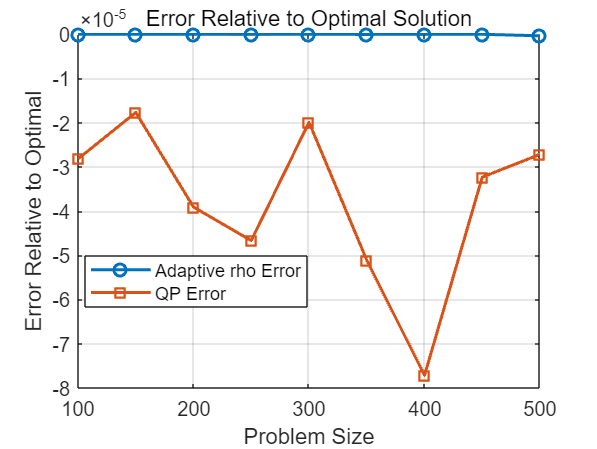

Optimal_500 = z'*H*z/2+g'*z;

% 问题规模
problem_sizes = [100, 150, 200, 250, 300, 350, 400, 450, 500];

% 对应的值
QP_values = [QP_100, QP_150, QP_200, QP_250, QP_300, QP_350, QP_400, QP_450, QP_500]; % 填入你记录的值
Update_rho_QP_values = [Scale_QP_100, Scale_QP_150, Scale_QP_200, Scale_QP_250, Scale_QP_300, Scale_QP_350, Scale_QP_400, Scale_QP_450, Scale_QP_500];
Optimal_values = [Optimal_100, Optimal_150, Optimal_200, Optimal_250, Optimal_300, Optimal_350, Optimal_400, Optimal_450, Optimal_500];

% 计算误差
Error_QP = QP_values - Optimal_values;
Error_Adaptive = Update_rho_QP_values - Optimal_values;


% 
% % 绘制目标函数值的折线图
figure;
% subplot(2, 1, 1); % 上图
% plot(problem_sizes, QP_values, '-o', 'LineWidth', 1.5, 'DisplayName', 'QP');
% hold on;
% plot(problem_sizes, Update_rho_QP_values, '-s', 'LineWidth', 1.5, 'DisplayName', 'QP with Adaptive rho');
% plot(problem_sizes, Optimal_values, '-^', 'LineWidth', 1.5, 'DisplayName', 'Optimal');
% 
% % 图例与标签
% legend('show');
% xlabel('Problem Size');
% ylabel('Objective Function Value');
% title('Objective Function Value Across Different Problem Sizes');
% grid on;



% 绘制误差的折线图
% subplot(2, 1, 2); % 下图
plot(problem_sizes, Error_QP, '-o', 'LineWidth', 1.5, 'DisplayName', 'QP Error');
hold on;
plot(problem_sizes, Error_Adaptive, '-s', 'LineWidth', 1.5, 'DisplayName', 'Adaptive rho Error');

% 图例与标签
legend('show', 'Location', 'best');
xlabel('Problem Size');
ylabel('Error Relative to Optimal');
title('Error Relative to Optimal Solution');
grid on;

function x = ADMM_QP_Adaptive(A1,A2,b1,b2, q, P)
    % Import necessary utility functions
    [A,l,u] = standard_constraints(A2,-b2,A1,-b1);
    sigma = 1e-6;
    alpha = 1.6;
    n = size(P, 1);
    m = size(A, 1);
    x = zeros(n,1);
    y = zeros(m,1);
    z = zeros(m,1);
    rho = 0.1;
    prim_tol = 1e-6;
    dual_tol = 1e-6;
    max_iter = 100;
    if n<100
        inner_loop = 50;
    elseif n<1000
        inner_loop  = 200;
    else
        inner_loop = 500;
    end
    
    function rho_estimate = compute_rho()
        RHO_MIN = 1e-06;
        RHO_MAX=1;
        DIVISION_TOL = 1e-20;
        prim_res_norm = norm(z,inf);
        temp_res_norm = norm(A*x,inf); 
        prim_res_norm = max(prim_res_norm, temp_res_norm);
        prim_res = prim_res/(prim_res_norm + DIVISION_TOL);
        
        dual_res_norm = norm(q,inf);
        temp_res_norm = norm(A'*y,inf);
        dual_res_norm = max(dual_res_norm, temp_res_norm);
        temp_res_norm = norm(P*x,inf);
        dual_res_norm = max(dual_res_norm, temp_res_norm);
        dual_res = dual_res/(dual_res_norm + DIVISION_TOL);
    
        rho_estimate = norm(rho * sqrt(prim_res / dual_res),inf);
        rho_estimate = min(max(rho_estimate, RHO_MIN), RHO_MAX);
    end
    for i = 1: max_iter
        for j = 1:inner_loop
            M = P + sigma * eye(n) + rho * (A'* A);
            b =  sigma* x - q + A'*(rho*z - y );
            x_tilde = conjgrad(M,b);
            z_tidle = A*x_tilde;
            x_next = alpha * x_tilde + (1 - alpha) * x;
            z_next = Pc(alpha * z_tidle + (1 - alpha) * z + 1 / rho * y, l, u);
            y = y + rho * (alpha * z_tidle + (1 - alpha) * z - z_next);
            z = z_next;
            prim_res = A*x-z;
            dual_res = P * x_next + q + A' * y;
    
            if norm(prim_res) <= prim_tol && norm(dual_res) <= dual_tol
                x = x_next;
                break;
            end
            x = x_next;
        end
        if norm(prim_res) <= prim_tol && norm(dual_res) <= dual_tol
            break;
        end
        rho = compute_rho();
    end
end

function x = ADMM_QP(A1,A2,b1,b2, q, P)
    % Import necessary utility functions
    [A,l,u] = standard_constraints(A2,-b2,A1,-b1);
    sigma = 1e-6;
    alpha = 1.6;
    n = size(P, 1);
    m = size(A, 1);
    x = zeros(n,1);
    y = zeros(m,1);
    z = zeros(m,1);
    rho = 1;
    prim_tol = 1e-4;
    dual_tol = 1e-6;
    max_iter = 2;
    if n<100
        inner_loop = 50;
    elseif n<1000
        inner_loop  = 200;
    else
        inner_loop = 500;
    end
    
    for i = 1: max_iter
        for j = 1:inner_loop
            M = P + sigma * eye(n) + rho * (A'* A);
            b =  sigma* x - q + A'*(rho*z - y );
            x_tilde = conjgrad(M,b);
            z_tidle = A*x_tilde;
            x_next = alpha * x_tilde + (1 - alpha) * x;
            z_next = Pc(alpha * z_tidle + (1 - alpha) * z + 1 / rho * y, l, u);
            y = y + rho * (alpha * z_tidle + (1 - alpha) * z - z_next);
            z = z_next;
            prim_res = A*x-z;
            dual_res = P * x_next + q + A' * y;
    
            if norm(prim_res) <= prim_tol && norm(dual_res) <= dual_tol
                x = x_next;
                break;
            end
            
            x = x_next;
        end
        if norm(prim_res) <= prim_tol && norm(dual_res) <= dual_tol
            break;
        end
    end
end